A = [infsup(0, 2), infsup(1, 3); 1, -infsup(2, 4); infsup(1, 3), 0];
b = [infsup(3, 7); 0; infsup(5, 7)];
Tol = @(A, b, x) min(rad(b) - mag(mid(b) - A * x));

[origtolmax,origargmax,envs,ccode] = tolsolvty(inf(A), sup(A), inf(b), sup(b));

 
 Допусковое множество решений интервальной линейной системы пусто 
 


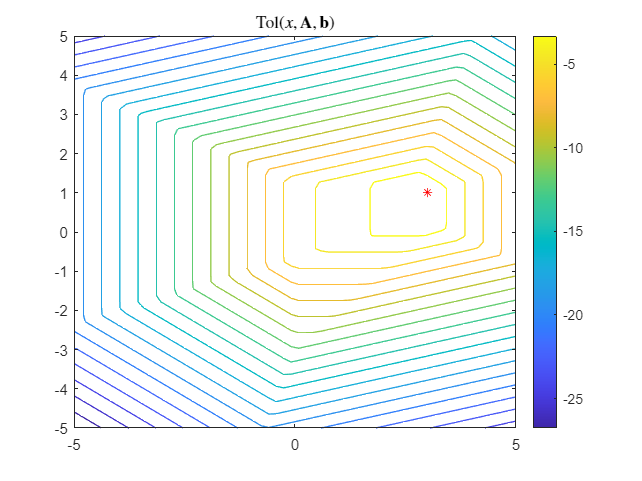

n = 60;
levels = n / 3;
x = linspace(-5, 5, n);
y = linspace(-5, 5, n);
[xx, yy] = meshgrid(x, y);
zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A, b, [xx(i, j); yy(i, j)]);
    end
end
figure
contour(xx, yy, zz, levels)
hold on
plot(origargmax(1), origargmax(2), 'r*')
hold on 
colorbar
title('Tol($x, \mathbf{A}, \mathbf{b}$)','interpreter','latex')

e = [infsup(-1, 1); infsup(-1, 1); infsup(-1, 1)];
C = 1.5 * abs(origtolmax);
b1 = b + C * e;
[btolmax,bargmax,envs,ccode] = tolsolvty(inf(A), sup(A), inf(b1), sup(b1));

 
 Допусковое множество решений интервальной линейной системы непусто 
 


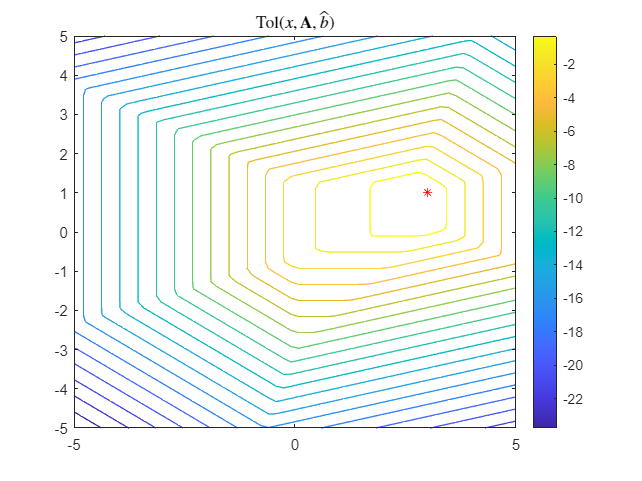

zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A, b1, [xx(i, j); yy(i, j)]);
    end
end
figure
contour(xx, yy, zz, levels)
hold on
plot(bargmax(1), bargmax(2), 'r*')
hold on 
colorbar
title('Tol($x, \mathbf{A}, \hat{b}$)','interpreter','latex')

[V,P1,P2,P3,P4] = EqnTolR2(inf(A), sup(A), inf(b1), sup(b1));

Число ориентиров = 6



iveVal = ive(A, b1);

 
 Допусковое множество решений интервальной линейной системы непусто 
 


rveVal = rve(A, b1);

 
 Допусковое множество решений интервальной линейной системы непусто 
 


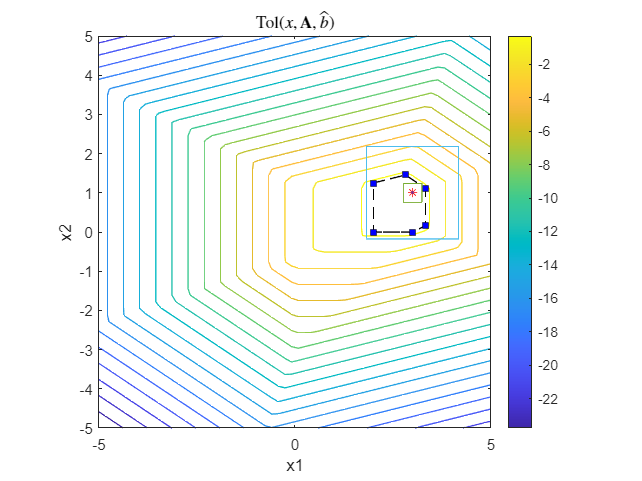

iveInt = [midrad(bargmax(1), iveVal);midrad(bargmax(2), iveVal)];
rveInt = [midrad(bargmax(1), rveVal);midrad(bargmax(2), rveVal)];
plotintval([iveInt, rveInt], 'n')

AETol = @(A, E, b, x) min(rad(b) - mag(mid(b) - A * x) + abs(E * x));
E = 1 * [1 1;0 1;1 0];
%E = infsup([-1 -1; -1 -1; -1 -1], [1 1; 1 1; 1 1]);
A1 = infsup(inf(A) + E, sup(A) - E);
zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A1, b, [xx(i, j); yy(i, j)]);
    end
end
[aetolmax,aeargmax,envs,ccode] = tolsolvty(inf(A1), sup(A1), inf(b), sup(b));

 
 Допусковое множество решений интервальной линейной системы непусто 
 


figure
contour(xx, yy, zz, levels)
hold on
plot(aeargmax(1), aeargmax(2), 'r*')
hold on 
colorbar
title('Tol($x, \hat{A}, \mathbf{b}$)','interpreter','latex')
[V,P1,P2,P3,P4] = EqnTolR2(inf(A1), sup(A1), inf(b), sup(b));

Число ориентиров = 2



iveVal = ive(A1, b);

 
 Допусковое множество решений интервальной линейной системы непусто 
 


rveVal = rve(A1, b);

 
 Допусковое множество решений интервальной линейной системы непусто 
 


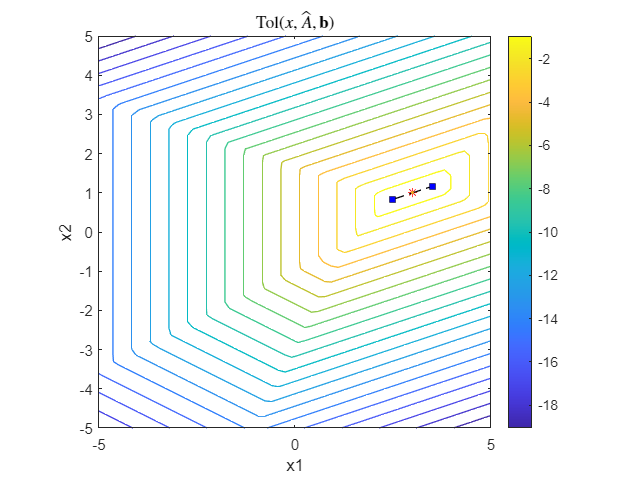

iveInt = [midrad(aeargmax(1), iveVal);midrad(aeargmax(2), iveVal)];
rveInt = [midrad(aeargmax(1), rveVal);midrad(aeargmax(2), rveVal)];
plotintval([iveInt, rveInt], 'n')

AENTol = @(A, E, b, x) min(rad(b) - mag(mid(b) - A * x) + abs(E * x));
N = [0.55 0 0;0 1 0;0 0 2/3];
E = 1 * N * [1 1;0 1;1 0];
%E = infsup([-1 -1; -1 -1; -1 -1], [1 1; 1 1; 1 1]);
A2 = infsup(inf(A) + E, sup(A) - E);
zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A2, b, [xx(i, j); yy(i, j)]);
    end
end
[aetolmax,aeargmax,envs,ccode] = tolsolvty(inf(A2), sup(A2), inf(b), sup(b));

 
 Допусковое множество решений интервальной линейной системы пусто 
 
 Абсолютное значение вычисленного максимума
                          находится в пределах заданной точности
 Перезапустите программу  с меньшими значениями  epsf и/или epsx
 для получения большей информации о разрешимости рассматриваемой
 задачи о допусках
 


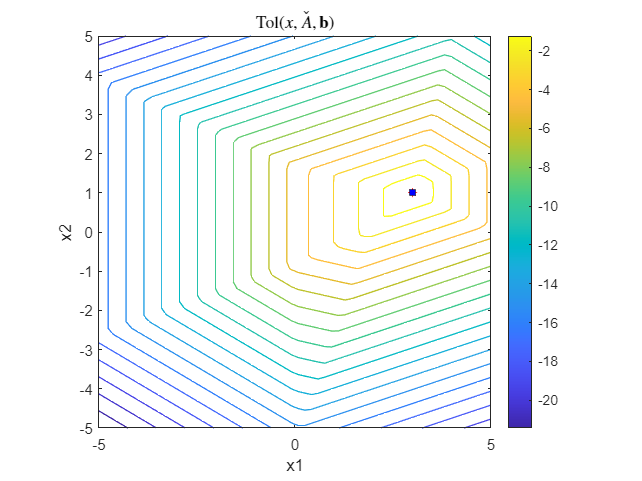

Число ориентиров = 1



figure
contour(xx, yy, zz, levels)
hold on
plot(aeargmax(1), aeargmax(2), 'r*')
hold on 
colorbar
title('Tol($x, \check{A}, \mathbf{b}$)','interpreter','latex')
[V,P1,P2,P3,P4] = EqnTolR2(inf(A2), sup(A2), inf(b), sup(b));

iveVal = ive(A2, b);

 
 Допусковое множество решений интервальной линейной системы пусто 
 
 Абсолютное значение вычисленного максимума
                          находится в пределах заданной точности
 Перезапустите программу  с меньшими значениями  epsf и/или epsx
 для получения большей информации о разрешимости рассматриваемой
 задачи о допусках
 


rveVal = rve(A2, b);

 
 Допусковое множество решений интервальной линейной системы пусто 
 
 Абсолютное значение вычисленного максимума
                          находится в пределах заданной точности
 Перезапустите программу  с меньшими значениями  epsf и/или epsx
 для получения большей информации о разрешимости рассматриваемой
 задачи о допусках
 


iveInt = [midrad(aeargmax(1), iveVal);midrad(aeargmax(2), iveVal)];

Error using midrad (line 31)
invalid radius in call of midrad

rveInt = [midrad(aeargmax(1), rveVal);midrad(aeargmax(2), rveVal)];
plotintval([iveInt, rveInt], 'n')